% Need to place vlfeature in the same directory as this file
run('vlfeat-0.9.21\toolbox\vl_setup.m');

% make it easier to do something
left = double(imread("br.jpg")) / 257 + 0.0001;
right = double(imread("t.jpg")) / 257  + 0.0001;
up = double(imread("bl.jpg")) / 257 + 0.0001
left = downsample2(left, 16);
right = downsample2(right, 16);
up = downsample2(up, 16);

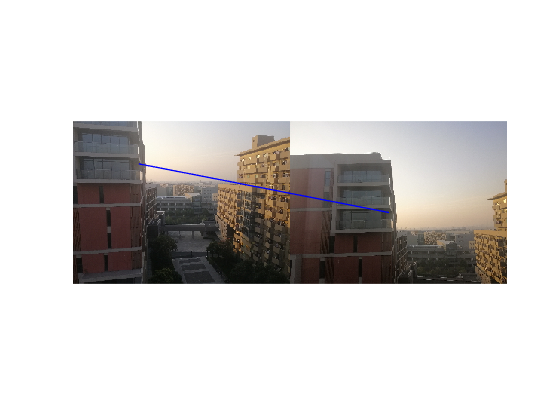

show_match(left, right, 1.2, "double");

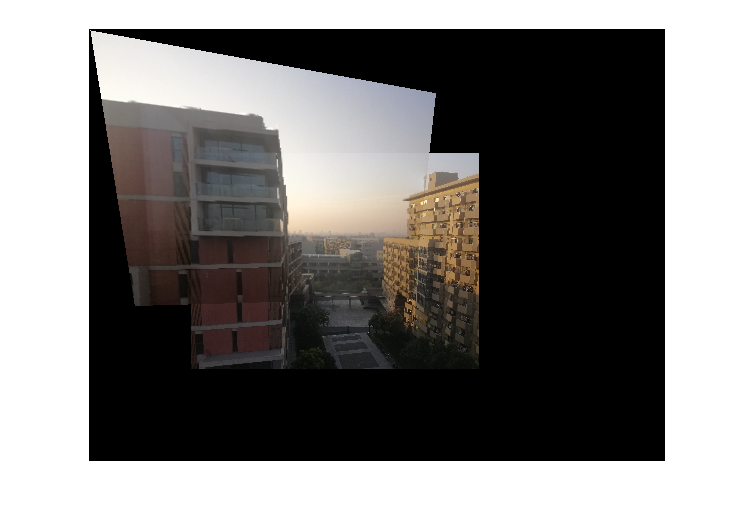

i = concatenate_image(left, right, 1.2, "double");
imshow(i)

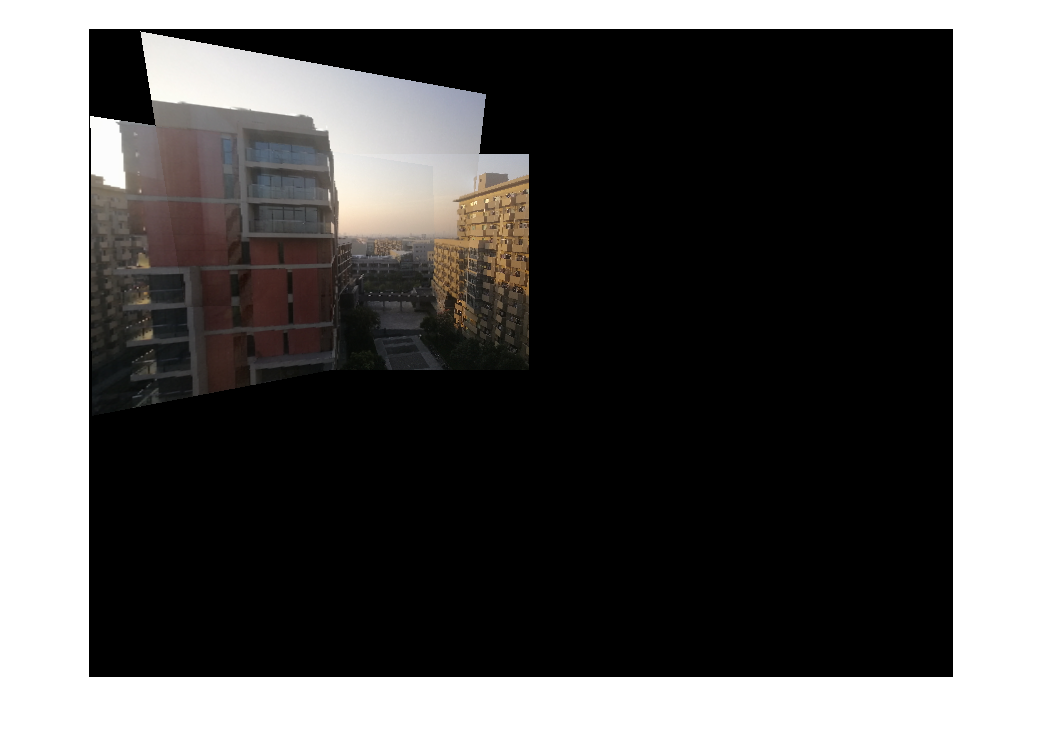

o = concatenate_image(i, up, 1.5, "double");
imshow(o)

function O = downsample2(I, factor)
    % downsample the image by an int-valued factor
    O = downsample(I, factor);
    O = permute(O, [2, 1, 3]);
    O = downsample(O, factor);
    O = permute(O, [2, 1, 3]);
end

function match = bi_dir_match(a, b, thres)
    % bi-directional sift matching
    a2b = single_dir_match(a, b, thres);
    b2a = single_dir_match(b, a, thres);
    [tf, ~] = ismember(flip(a2b, 2), b2a, 'rows');
    match = a2b(tf,:);
end

function match = single_dir_match(a, b, thres)
    % single direction sift matching
    a_shape = size(a);
    a = double(a);
    b = double(b);
    match = zeros([a_shape(1), 2], 'int32');
    counter = 1;
    for i = 1 : a_shape(1)
        [t, min] = mink(norms(b - a(i,:), 2, 2), 2);
        if thres * t(1) < t(2)
           match(counter,:) = [i, min(1)];
           counter = counter + 1;
        end
    end
    match = match(1:counter-1,:);
end

function show_match(left, right, thres, config)
    % show the matches between keypoints between 2 images
    [fa,da] = vl_sift(im2single(rgb2gray(left))) ;
    [fb,db] = vl_sift(im2single(rgb2gray(right))) ;
    
    if config == "single"
        matches = flip(single_dir_match(da', db', thres)', 2);
    else
        matches = flip(bi_dir_match(da', db', thres)', 2);
    end
    
    newsize_x = max(size(left, 1), size(right, 1));
    newsize_y = max(size(left, 2), size(right, 2));
    
    newleft = zeros([newsize_x, newsize_y, 3], 'like', left);
    newright = zeros([newsize_x, newsize_y, 3], 'like', left);
    
    newleft(1:size(left,1), 1:size(left, 2), :) = left;
    newright(1:size(right,1), 1:size(right, 2), :) = right;
    
    figure(1) ; clf ;
    imagesc(cat(2, newleft, newright)) ;
    
    xa = fa(1,matches(1,:));
    xb = fb(1,matches(2,:)) + size(newleft,2);
    ya = fa(2,matches(1,:));
    yb = fb(2,matches(2,:));
    
    hold on;
    h = line([xa ; xb], [ya ; yb]);
    set(h,'linewidth', 1, 'color', 'b');
    
    axis image off;
    hold off;
end

function I = concatenate_image(left, right, thres, config)
    % the main function to perform concatenating between 2 images
    [fa,da] = vl_sift(im2single(rgb2gray(left))) ;
    [fb,db] = vl_sift(im2single(rgb2gray(right))) ;
    
    if config == "single"
        matches = flip(single_dir_match(da', db', thres)', 2);
    else
        matches = flip(bi_dir_match(da', db', thres)', 2);
    end
    
    xa = fa(1,matches(1,:));
    xb = fb(1,matches(2,:));
    ya = fa(2,matches(1,:));
    yb = fb(2,matches(2,:));
    
    X = [xa; ya]';
    Y = [xb; yb]';
    
    transform = ransac_project(X, Y);

    I = merge_img_with_transform(left, right, transform);
end

function b = inlier(X, Y, T, eps)
    % if X Y pair is a inlier
    A = X*T;
    A = A ./ A(3); 
    d = norm(A - Y, 1); 
    b = d < eps;
end

function Affine_transform = calculate_affine_trans(Y, X)
    % another method to find the 
    for i = 1:5
        h = size(Y);
        h = h(1);
        H = eye([h, h]);
        for j = 1:h -1
            H(j, j+1) = -1;
        end
        H(h, 1) = -1;
    
        cvx_begin
            variable R(2,2);
            variable T_P(h,2);
            
            minimize(sum(norms(X*R + T_P - Y, 1, 2)));
            
            subject to
                H*T_P == 0
        cvx_end
        
        m = mean(sqrt(sum((X*R + T_P(1,:) - Y).^2, 2)));
        t = size(X);
        t = t(1);
        j = 1;
        while j <= t
            if sqrt(sum((X(j, :)*R + T_P(1,:) - Y(j,:)).^2)) > 3 * m
                X(j, :) = [];
                Y(j, :) = [];
                t = size(X);
                t = t(1);
            else
                j = j + 1;
            end
        end
    end
    T = T_P(1,:);
    
    Affine_transform = affine2d([
        R(1,1), R(1,2), 0;
        R(2,1), R(2,2), 0;
        T(1), T(2), 1;
    ]);
end

function best_model = ransac_project(y, x)
    % using ransac to find the best (approximatelt affine) transform model
    x = [x, ones([size(x, 1), 1])];
    y = [y, ones([size(x, 1), 1])];
    
    max_iter = 100;
    max_inlier = 0;
    
    for i = 1 : max_iter
        sampled_index = randsample(size(x, 1), 4);
        T = calculate_T_project(x(sampled_index, :), y(sampled_index, :));
        inlier_counter = 0;
        for j = 1 : size(x, 1)
            inlier_counter = inlier_counter + inlier(x(j, :), y(j,:), T, 5);
        end
        if inlier_counter > max_inlier
            max_inlier = inlier_counter;
            best_model = T;
        end
    end
    
    X_ = zeros(size(x), 'like', x);
    Y_ = zeros(size(y), 'like', y);
    counter = 1;
    for j = 1 : size(x, 1)
        if inlier(x(j, :), y(j,:), best_model, 5)
            X_(counter, :) = x(j, :);
            Y_(counter, :) = y(j, :);
            counter = counter + 1;
        end
    end
    X_ = X_(1:counter - 1, :);
    Y_ = Y_(1:counter - 1, :);
    
    best_model = projective(X_, Y_);
end

function T = calculate_T_project(X, Y)
    M = size(X,1);
    x = X(:,1);
    y = X(:,2);
    vec_1 = ones(M,1);
    vec_0 = zeros(M,1);
    u = Y(:,1);
    v = Y(:,2);
    U = [u; v];
    A = [x      y      vec_1  vec_0  vec_0  vec_0  -u.*x  -u.*y;
         vec_0  vec_0  vec_0  x      y      vec_1  -v.*x  -v.*y  ];
    t = A \ U;
    t(9) = 1;
    T = reshape(t,3,3);
end

function transform = projective(X, Y)
    T = calculate_T_project(X, Y);
    transform = projective2d(T);
end

function I = merge_img_with_transform(L, R, Affine)
    % concatenate L and R using affine transform
    [B, RB] = imwarp(R, Affine);

    L_shape = size(L);
    R_shape = size(R);
    t = L_shape + R_shape;
    T_1 = zeros([t(1), t(2), 3]);
    T_2 = zeros([t(1), t(2), 3]);
    
    t = size(B);
    x_s = int32(RB.XWorldLimits(1));
    x_e = x_s + t(2) - 1;
    y_s = int32(RB.YWorldLimits(1));
    y_e = y_s + t(1) - 1;
    
    x_offset = 2;
    y_offset = 2;
    
    if x_s <= 0
        x_offset = -x_s + 1;
    end
    if y_s <= 0
        y_offset = -y_s + 1;
    end
    t = size(L);
    T_1(y_offset:y_offset+t(1) - 1, x_offset:x_offset+t(2) - 1, :) = L;
    T_2(y_s+y_offset:y_e+y_offset, x_s+x_offset:x_e+x_offset,:) = B;
    
    non_zero_1 = mean(T_1,3) ~= 0;
    non_zero_2 = mean(T_2,3) ~= 0;
    
    mask = non_zero_1 .* non_zero_2;
        
    [B, ~, I] = boundary_mask(mask);
    back = (1-mask) .* T_1 + (1-mask).*T_2 + B.*(T_1+T_2)/2;
    source = T_2;
    I = importing_gradients(back, source, I);
    
end

function [map, inv_map] = make_map(mask)
    [x, y] = size(mask);
    
    % calculate all the number of pixels in the interior
    inner_entries = int32(sum(sum(uint8(mask))));
    
    % map from index of variables to location in the image
    [r, c] = find(mask);
    map = [r c];
    
    % map from location in the image to index of variables
    inv_map = zeros([x, y], 'uint32');
    % assign values to inv_map
    indices = 1:inner_entries;
    r = map(indices, 1);
    c = map(indices, 2);
    idx = sub2ind(size(inv_map), r,c);
    inv_map(idx) = indices;
end

function [B, mask, int] = boundary_mask(M)
    kernel = [0,1,0;1,0,1;0,1,0];
    B = (M .* filter2(kernel, double(1-M)) > 0);
    mask = (M .* filter2(kernel, filter2(kernel, filter2(kernel, filter2(kernel, double(1-M))))) > 0);
    mask = (1-B).*mask;
    int = M .* (1-B);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Seamless clone part

% check inner
function flag = is_inner(x_, y_, x, y)
    flag = 1 <= x_ & x_ <= x & 1 <= y_ & y_ <= y;
end
% generate the seamless cloned image from background image, source image
% and mask
function out_put_image = importing_gradients(background_image, source_image, mask)
   % generate the 2 maps
   [map, inv_map] = make_map(mask);
   
%% generate the Poisson equation            
   [num_entries, ~] = size(map);
   % The coefficients of the equation Mq = b
   M = spalloc(num_entries, num_entries, num_entries * 5);
   b = zeros([num_entries, 3]);
   % The canvas of the output
   image = zeros(size(background_image), 'like', background_image);
   [x, y, ~] = size(background_image);
   tmp = zeros([x, y], 'like', background_image);
   % The kernel to help calculate the gradients
   kernel = [
       0, -1, 0;
       -1, 4, -1;
       0, -1, 0];
   % calculate the gradients in each channel
   
   % importing gradients
   gradients(:, :, 1) = conv2(source_image(:,:,1), kernel, 'same');
   gradients(:, :, 2) = conv2(source_image(:,:,2), kernel, 'same');
   gradients(:, :, 3) = conv2(source_image(:,:,3), kernel, 'same');

   % To make code simpler, embed all the offsets of neighbour into one
   % vector
   directions = [1, 0; -1, 0; 0, 1; 0, -1];
   % calculate the coefficients of the Poisson equation i.e.
   % |N_p| f_p - sum(f_q) = sum(f_q^*) + sum(v_pq)
   for i = 1:num_entries
      pos = map(i, :);
      neighbours = 0;
      for k = 1:4
          temp = pos + directions(k, :);
          % the pixel needs to be in the image
          if is_inner(temp(1), temp(2), x, y)
              % add -sum(f_q) to the coefficient matrix
              if mask(temp(1), temp(2))
                  ind = inv_map(temp(1), temp(2));
                  M(i, ind) = -1;
              else
                  % add boundary conditions
                  b(i,:) = b(i,:) + reshape(double(background_image(temp(1), temp(2),:)), [1,3]);
              end
              neighbours = neighbours + 1;
          end
      end
      % |N_p| f_p
      M(i, i) = neighbours;
      % sum(v_pq)
      b(i,:) = b(i,:) + reshape(gradients(pos(1), pos(2),:), [1,3]);
   end   
   
%% solve the linear system, poisson equation
   sol = M \ b;
   % color the image by the solution of the linear system.  
   L = 1 : num_entries; 
   r = map(L,1);
   c = map(L,2);
   % change the (i, j) indices parts into integer indices
   idx = sub2ind(size(inv_map), r,c);
   % color each channel
   tmp(idx) = sol(:,1);
   image(:, :, 1) = tmp;
   tmp(idx) = sol(:,2);
   image(:, :, 2) = tmp;
   tmp(idx) = sol(:,3);
   image(:, :, 3) = tmp;
   % generate the final image
   out_put_image = double(mask) .* image + double(1 - mask) .* background_image;
end